% clear
% N=100;
% L=zeros(N,N);
% eig2=0;
% while(eig2<0.001)
% L=zeros(N,N);    
% for i=1:N
%     p=0;
%     while(p<0.6)
%         p=rand;
%     end
%     for j=i+1:N
%         if(rand>p)
%             L(i,j)=-1;
%             L(j,i)=-1;
%         end
%     end
%     L(i,i)=-sum(L(i,1:N));
% end
% eigen=eig(L);
% eig2=eigen(2);
% end
% L
% eig(L)
% D=zeros(N,N);
% while(D==zeros(N,N))
% for i=1:N
%     if(rand>0.9)
%         D(i,i)=1;
%     end
% end
% end
% sum(D,2)
% 
% while(1)
%     L1=L;
%     K=N;
%     for i=1:N
%         if(rand>0.9)
%             for j=1:K
%                 L1(j,j)=L1(j,j)+L1(j,i);
%                 L1(i,j)=0;
%                 L1(j,i)=0;
%             end
%             L1(i,:)=[];
%             L1(:,i)=[];
%             K=K-1;
%         end
%     end
%     eigen=eig(L1);
%     eig2=eigen(2);
%     if(eig2>0.001)
%         break;
%     end
% end

% clear
df_t1=zeros(1,200001)

df_t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dPti_t=zeros(1,200001)

dPti_t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


u_P=0;
KP=-0.005;
KI=-0.01;
c_P=0;
c_I=0;
XP=zeros(4,1)   %df dPti dXgi dPgi 

XP =      0
     0
     0
     0



TH=0.1;
TD=0.002;
TCA=4;
TCB=30;
TT=0.2;
TG=0.3;
RG=3.6;
% g=0.795;
AT=[-TD/2/TH,1/2/TH,0,0;
    0,-1/TT,1/TT,0;
    -TCA/TCB/TG/RG,0,-1/TCB,(TG-TCA)/TCB/TG;
    -1/RG/TG,0,0,-1/TG];
BT=[0;0;TCA/TCB/TG;1/TG];
H=[-1/2/TH;0;0;0];

% dPL=0;
for t=0:0.01:500
%     if(t>220)
%         dPL=0.03;
%     end
    n=round(t/0.01)+1;
    c_I=c_I+0.01*XP(1);
    c_P=XP(1);
      u_P=KP*c_P+KI*c_I;
    XP=XP+0.01*( AT*XP + BT*u_P + H*0.8*dPL(n));
    df_t1(n)=XP(1);
    dPti_t(n)=XP(4);
end

XP

XP =    -0.0522
    0.0003
    0.0005
    0.0128


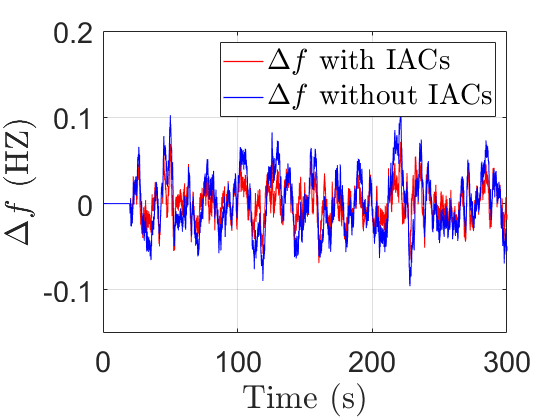

t=0:0.01:500;
figure(4)
clf
plot(t(20001:length(t))-200,df_t(20001:length(t)),"LineWidth",1,'Color','r')
hold on
plot(t(20001:length(t))-200,df_t1(20001:length(t)),"LineWidth",1,'Color','b')
grid on
ylim([-0.15 0.2])
set(gca,'FontSize',22);
% set(gca,'ytick',-0.8:0.2:50+0.4);
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$\Delta f$ (HZ)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
legend({['$\Delta f$ with IACs'],['$\Delta f$ without IACs']},"Interpreter","latex",'FontSize',22)

% plot(t,dPti_t(1:length(t)),"LineWidth",2,'Color','b')
% grid on

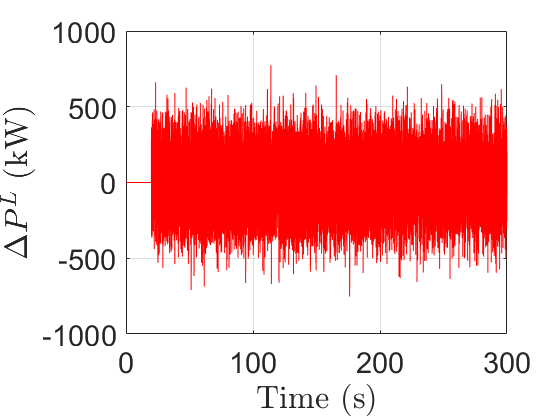

figure(5)
clf
plot(t(20001:length(t))-200,3600*dPL(20001:length(t)),"LineWidth",1,'Color','r')
grid on
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$\Delta P^{L}$ (kW)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

% legend({['$\Delta f$ with IACs'],['$\Delta f$ without IACs']},"Interpreter","latex",'FontSize',22)